# **IO135 - IO316 Inter-Module Synchronization Loopback**

The IO135 I/O module is a fast, simultaneous-sampling, 16-bit analog input and output module, complete with dedicated Simulink® driver blocks.

The IO316 I/O module is a configurable I/O module offering 100k logic cells and 64 ESD-protected TTL I/O lines and an AMD® Spartan®-6 chip

This example demonstrates the combination of an IO135 module, offering ADC measurement functionality, and an IO316 configurable module. The main focus is to demonstrate the setup where the IO316 module generates user-defined PWM signals and synchronized sample signals that can be used with the inter-module synchronization feature of the IO135.

**Note that the same example can be used** by replacing the IO135 **with the IO132, IO133 or IO134**. If you do so, note that the IO13x pin numbers will be different compared to this specific example. You can use any 3 of the analog input pins available on the respective IO132-IO135 module present in your system. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO135 and one IO316 I/O module installed

- A Speedgoat configuration file that supports at least **6x PWM channels including A lines, where the first 3 PWM lines are reserved for the synchronization feature.** Note that you also need a special rear-I/O functionality if you want to run in internal connection mode (see below)

- Connector cable from the I/O modules to the terminal boards

- 2x 50-pin terminal board and 1x 68-pin terminal board with jumper wires

### Test Setup

Note that the first 3 PWM channels of the IO316 are used to synchronize the IO135. There are 2 options available:

#### 1: Internal Connection (Rear I/O)

Both I/O modules are already internally connected (via P14) to ensure the inter-module-synchronization functions correctly. In this case, the IO316 cannot be extended with additional IOs (e.g. IO3xx_21 or IO3xx_22). Note that the first 3 PWM channels of the IO316 (located on pins 1, 11 and 20 on the IO316 terminal board) are reserved and represent the synchronization signals. They can't be used for user PWM functionality.

Connect the IO135 modules with the P2 cable to a 50-pin terminal board, and the IO316 to a 68-pin terminal board. On the terminal board of the IO316, locate the PWM channels 4-6 (A-Channel) and connect them to analog inputs 1, 9 and 17 of the IO135 terminal board (P2) positive (+) pins. Also connect the corresponding negative (-) pins of the analog I/O module to GND.

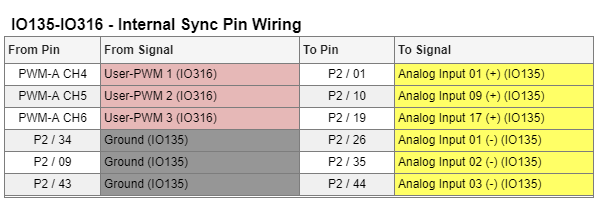

#### 2: External Connection (Front I/O)

The IO316 is extended with additional IOs (e.g. IO3xx_21 or IO3xx_22) and cannot be internally connected (via P14) to the IO135 synchronization. Note that in this case, the first 3 PWM channels of the IO316 (located on Pins 1, 11 and 20 on the IO316 terminal board) must be externally connected to the synchronization lines on pins 22, 23 and 24 of the IO135 terminal board (P3). They can't be used for user PWM functionality.

Connect the IO135 modules with the P3 and the P2 cables to two 50-pin terminal boards, and the IO316 to a 68-pin terminal board. Connect the synchronization signals on the P3 terminal board as described above. On the terminal board of the IO316, locate the PWM channels 4-6 (A-Channel) and connect them to analog inputs 1, 9 and 17 of the IO135 terminal board (P2) positive (+) pins. Also connect the corresponding negative (-) pins of the analog I/O module to GND.

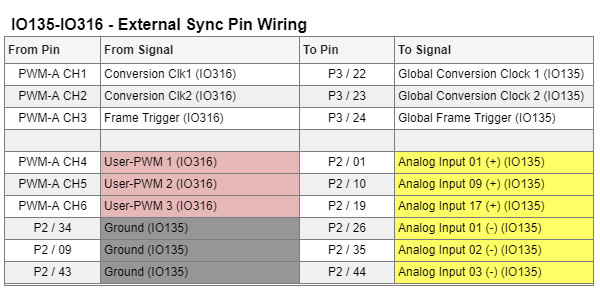

[IO135 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io135_pin_mapping)

## Initialize and Open the Simulink model

Open the Simulink model and choose your appropriate connection by commenting out the unwanted configuration block.

 
% Open Simulink model
modelName = 'sgMdl_IO135_IO316_InterModuleSyncLoopback';
open_system(modelName);
% Mandatory: set the model time step to 10ms
set_param(modelName, 'FixedStep', '10e-3');

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

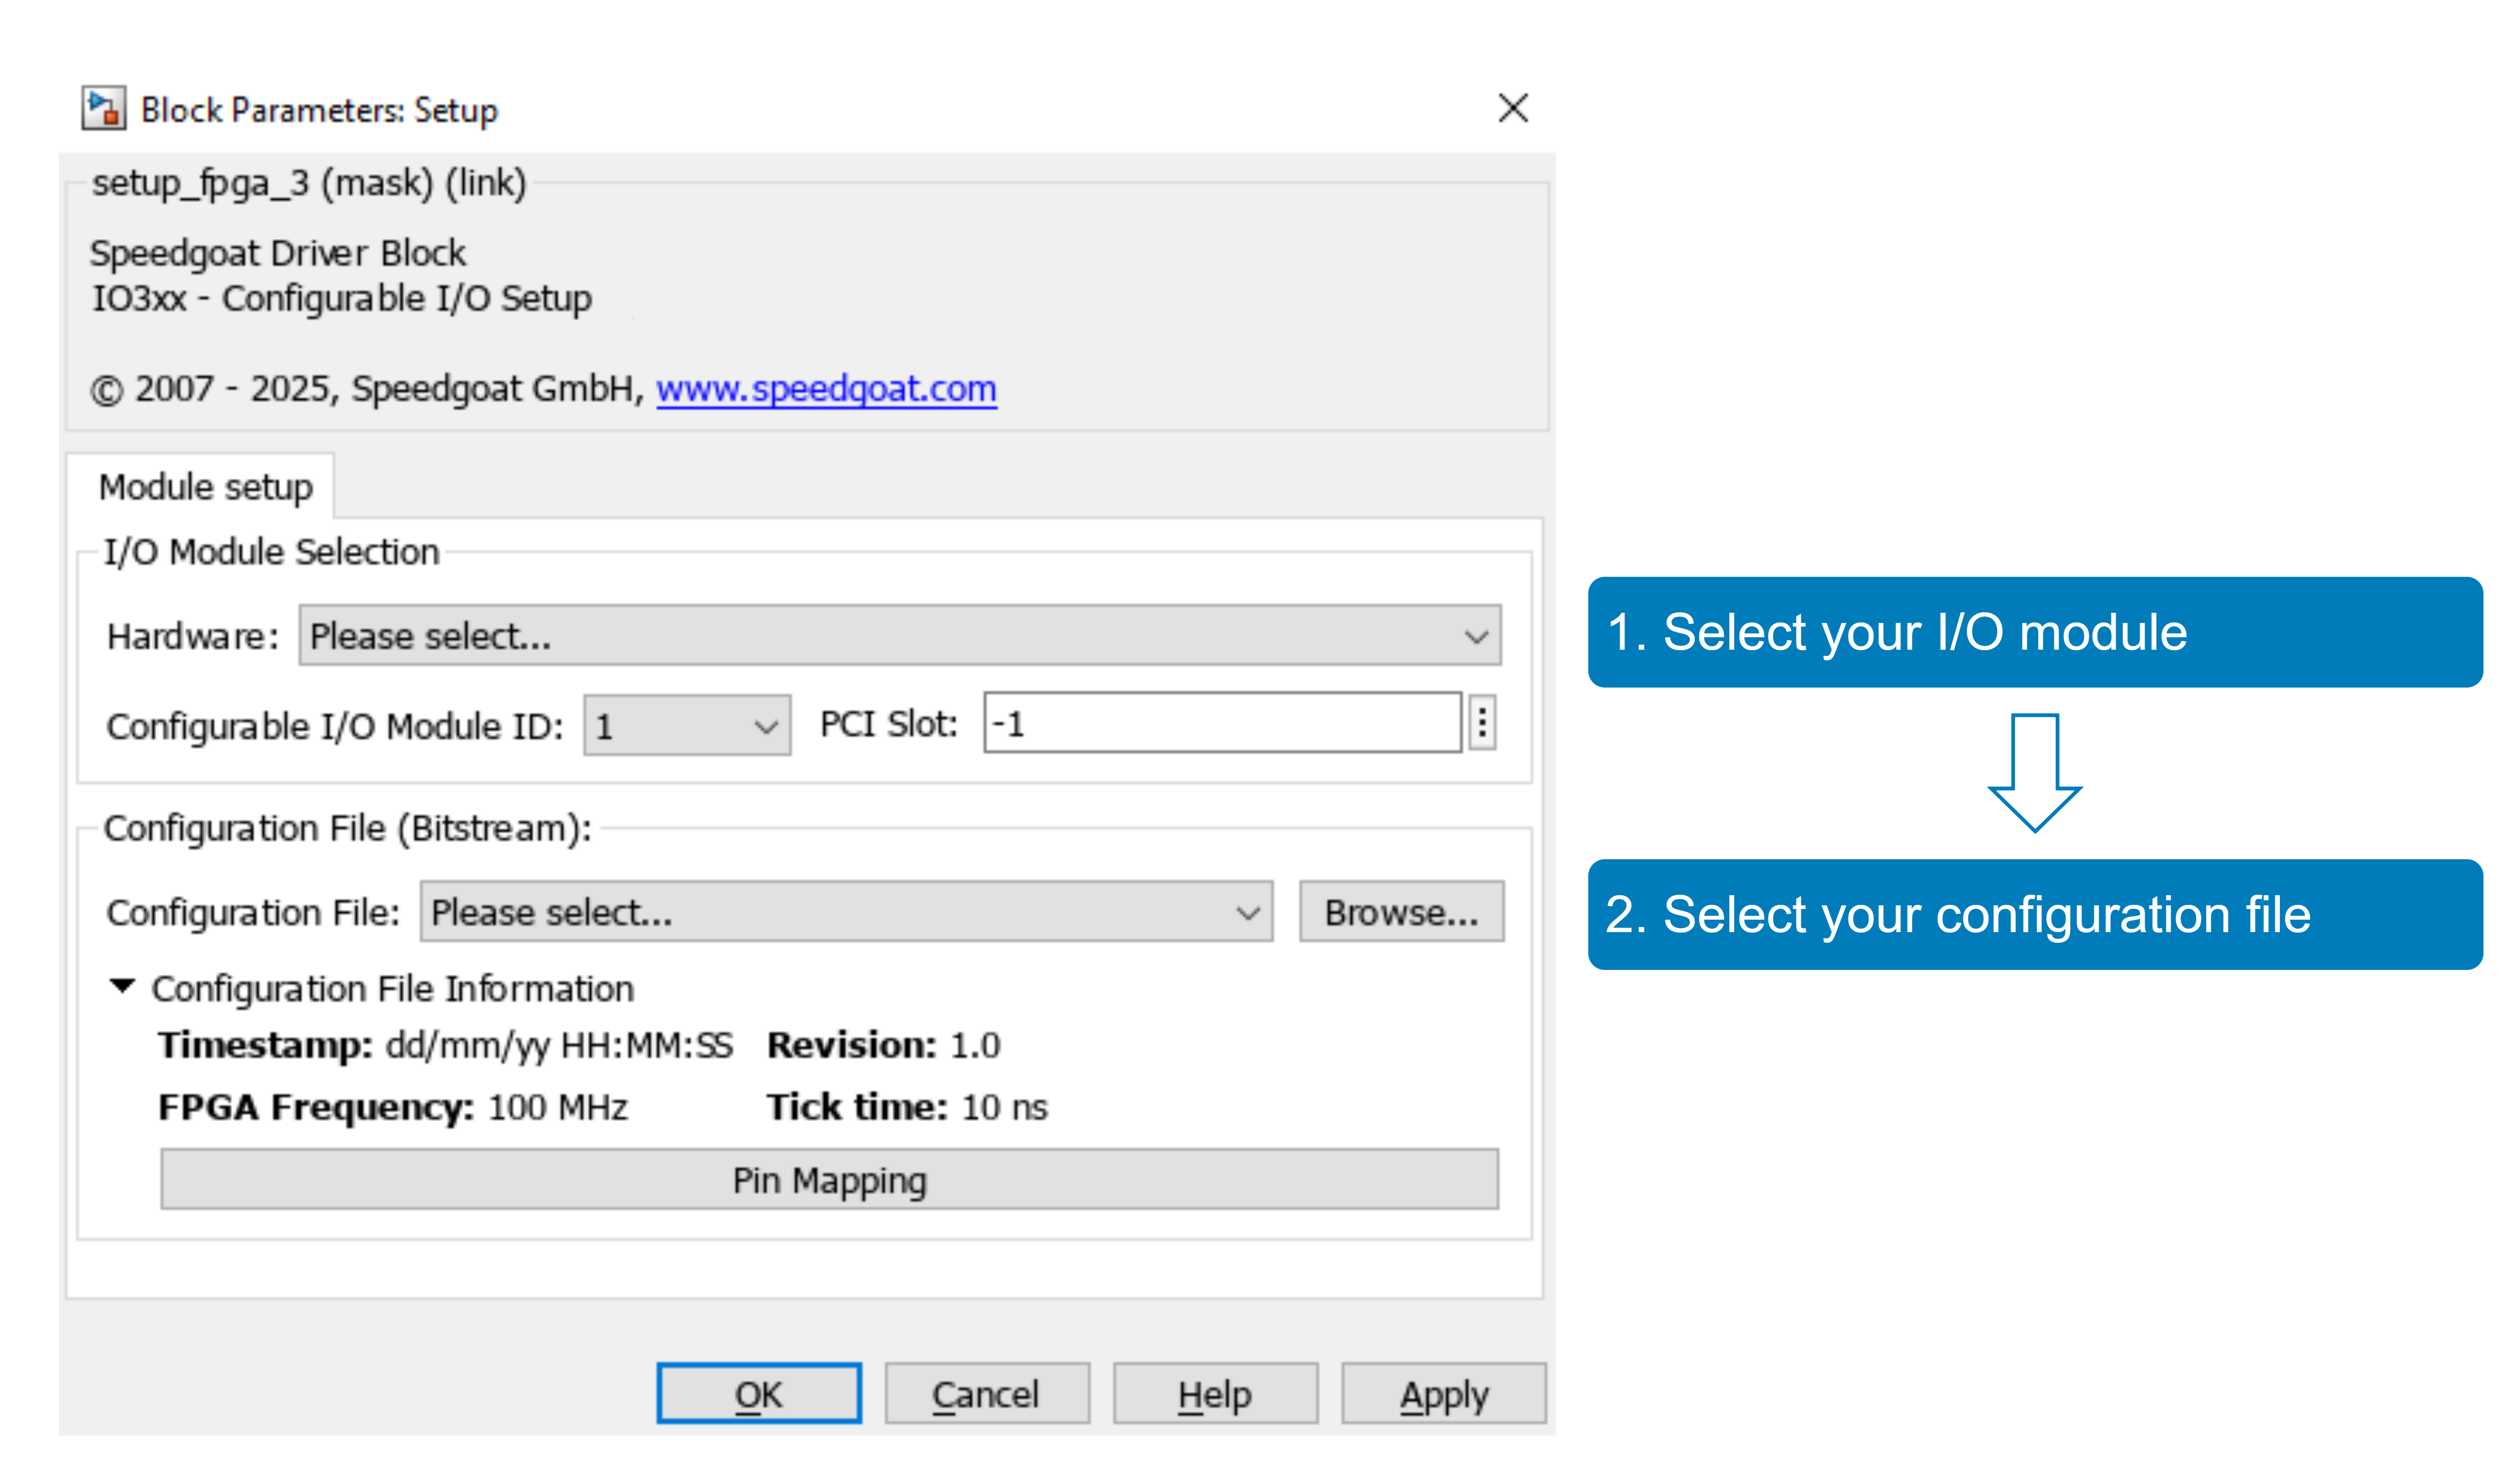

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### General Setup

The Simulink model features the IO135 Setup and Analog Input blocks. Analog inputs are enabled in the Setup block. Furthermore, the model features the IO316 Setup and the Speedgoat IO Sync and PWM Generation block that generates the IO135 synchronization and the user PWM signals. A Speedgoat Interrupt Setup block, configured as the model trigger, is also used. If you wish to reuse the example in a larger Simulink model, consider placing the blocks into a function-triggered subsystem and configuring the Interrupt Setup block accordingly. Additionally, in this example, the inter-module synchronization is enabled. This ensures that the analog inputs are synchronized to the user PWM signals.

### Internal/External Sync Pin Wiring

Note that this example is intended for the internal synchronization pin wiring. If you want to change to external sync pin wiring (sync wires connection via front IOs of the modules), open the **IO135 Setup** block mask, and change the **Inter-Module Synchronization **parameter (**Main** Tab) to **Target - Front I/O**.

### PWM Signal Generation and Analog Measurement

In the block mask of** IO Sync and PWM Generation**, the **Desired base PWM period** is set to 10 ms (**PWM generation** tab). On the **Intermodule Sync** tab, the **Sampling Mode** is set to **Multiple samples per period** and the **Number of samples per period** is set to 1000. In the same tab below, the mask indicates how to set the ADC parameters in the **IO135 Setup** Block.

This means we are generating PWM signals with 100 Hz period. The 0 V LOW/3.3 V HIGH PWM signals are therefore sampled a 1000 times for each period. Since we use DMA in the IO135, these 1000 measurements are available in every sample step of the model. All these samples are then totalled to obtain one result.

The following image shows an example for a 50 % duty-cycle, right-aligned PWM:

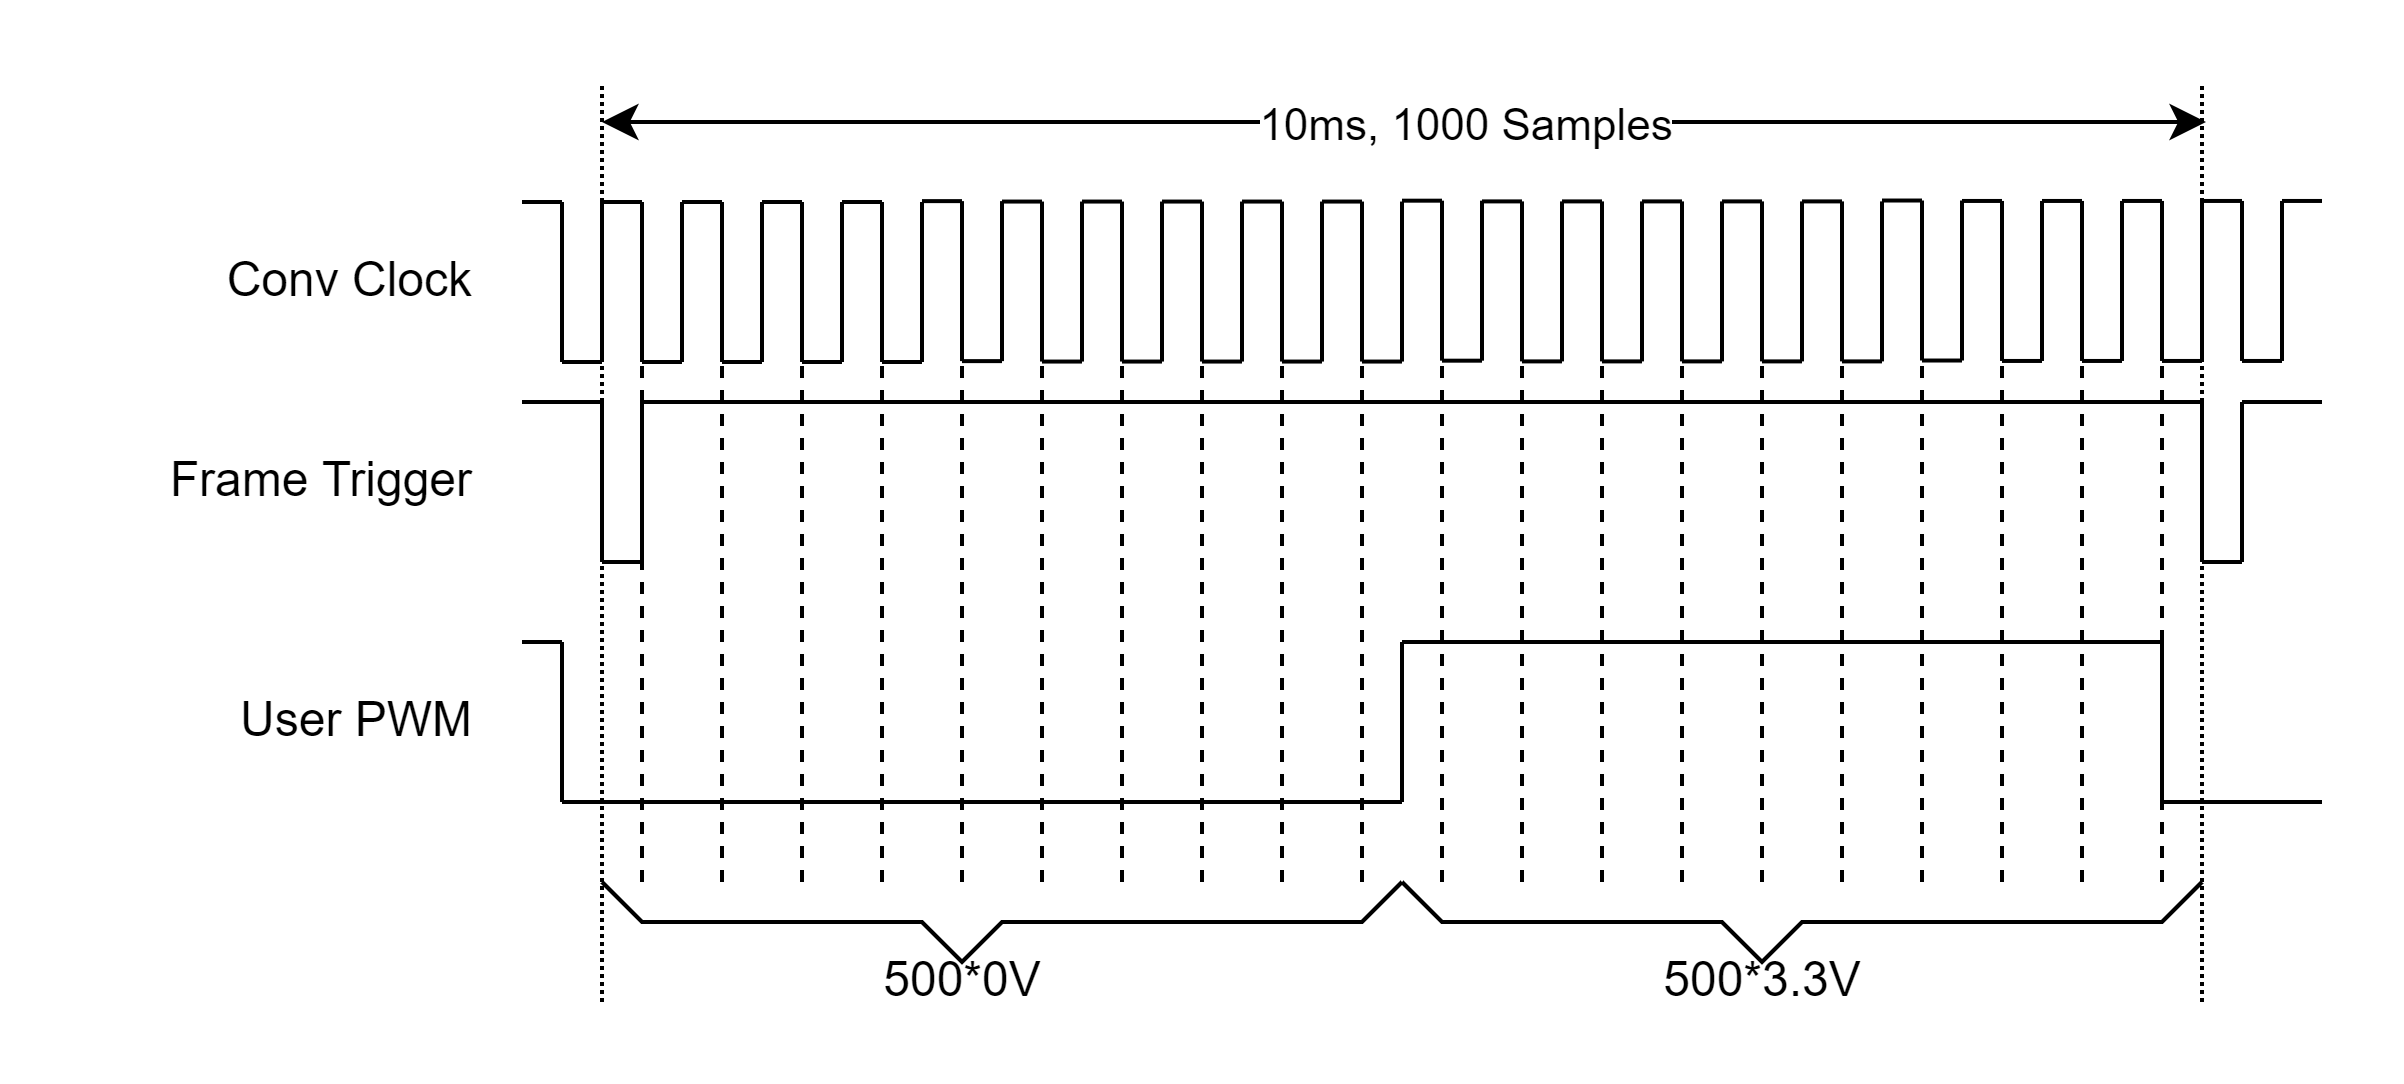

This means the measured and totalled PWM values have a maximum of 3,300 (3.3 V*1000 samples) and a minimum of 0 (0 V * 1000 samples) depending on the PWM's duty-cycle.

The example model uses a sine wave signal, setting the duty cycle between 0 and 1 (means 0 % and 100 %). Furthermore, 3 different PWM channels are generated with a phase shift of 120° between each.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application and open the SDI-Viewer
stoptime = 10; % Simulation length [s]

tg.setStopTime(stoptime);
% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(stoptime+1)
tg.stop;


### Check the Results

#### Scope_PWM_DC

The scope shows you the duty cycles of the PWM Generation:

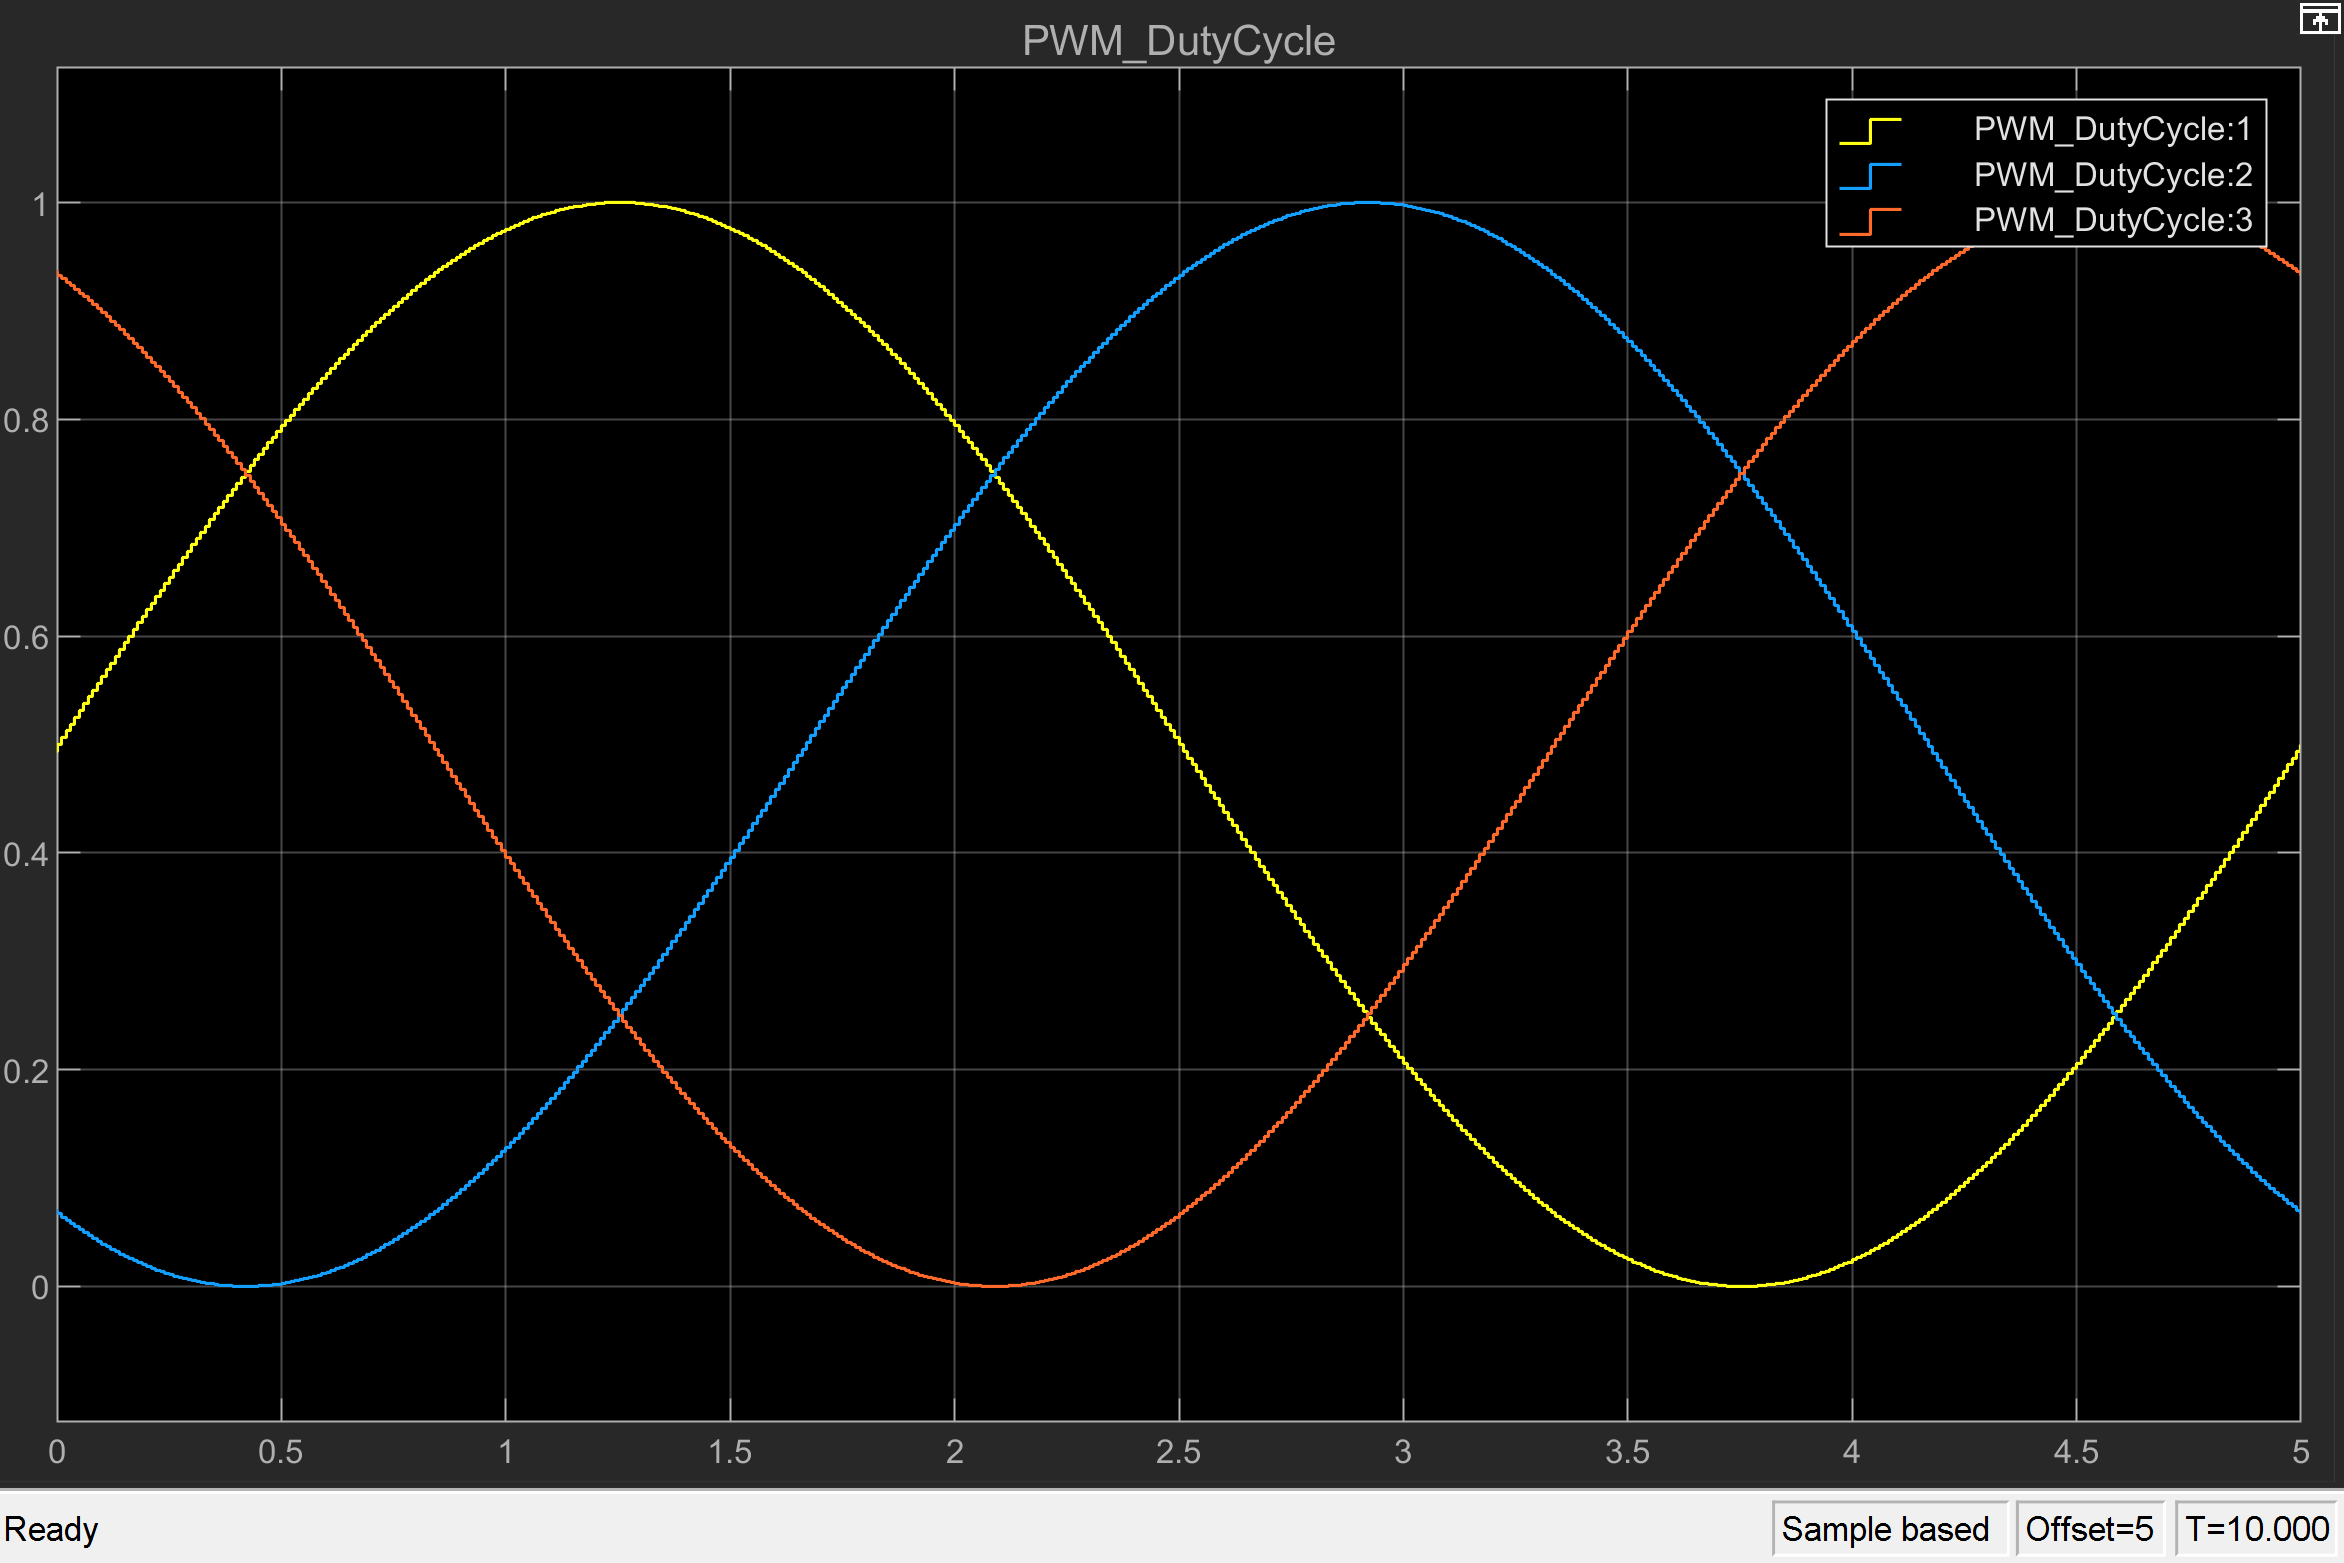

The duty cycles are sine-wave signals with 120° phase shift and set the full range of PWM signals (0-100% Duty Cycle)

#### Scope_PWM_Analog

The scope shows the PWM signals that have been measured by the IO135 analog inputs. As described above, one PWM Period is measured in 1000 equidistant samples. All these samples are then totalled to obtain one result. The signals from this scope must be identical to the signals from the above scope. However, since the analog module measures PWM off = 0 V and PWM on = 3.3 V and we always total 1000 samples, the sine wave value varies between 0 and 3300.

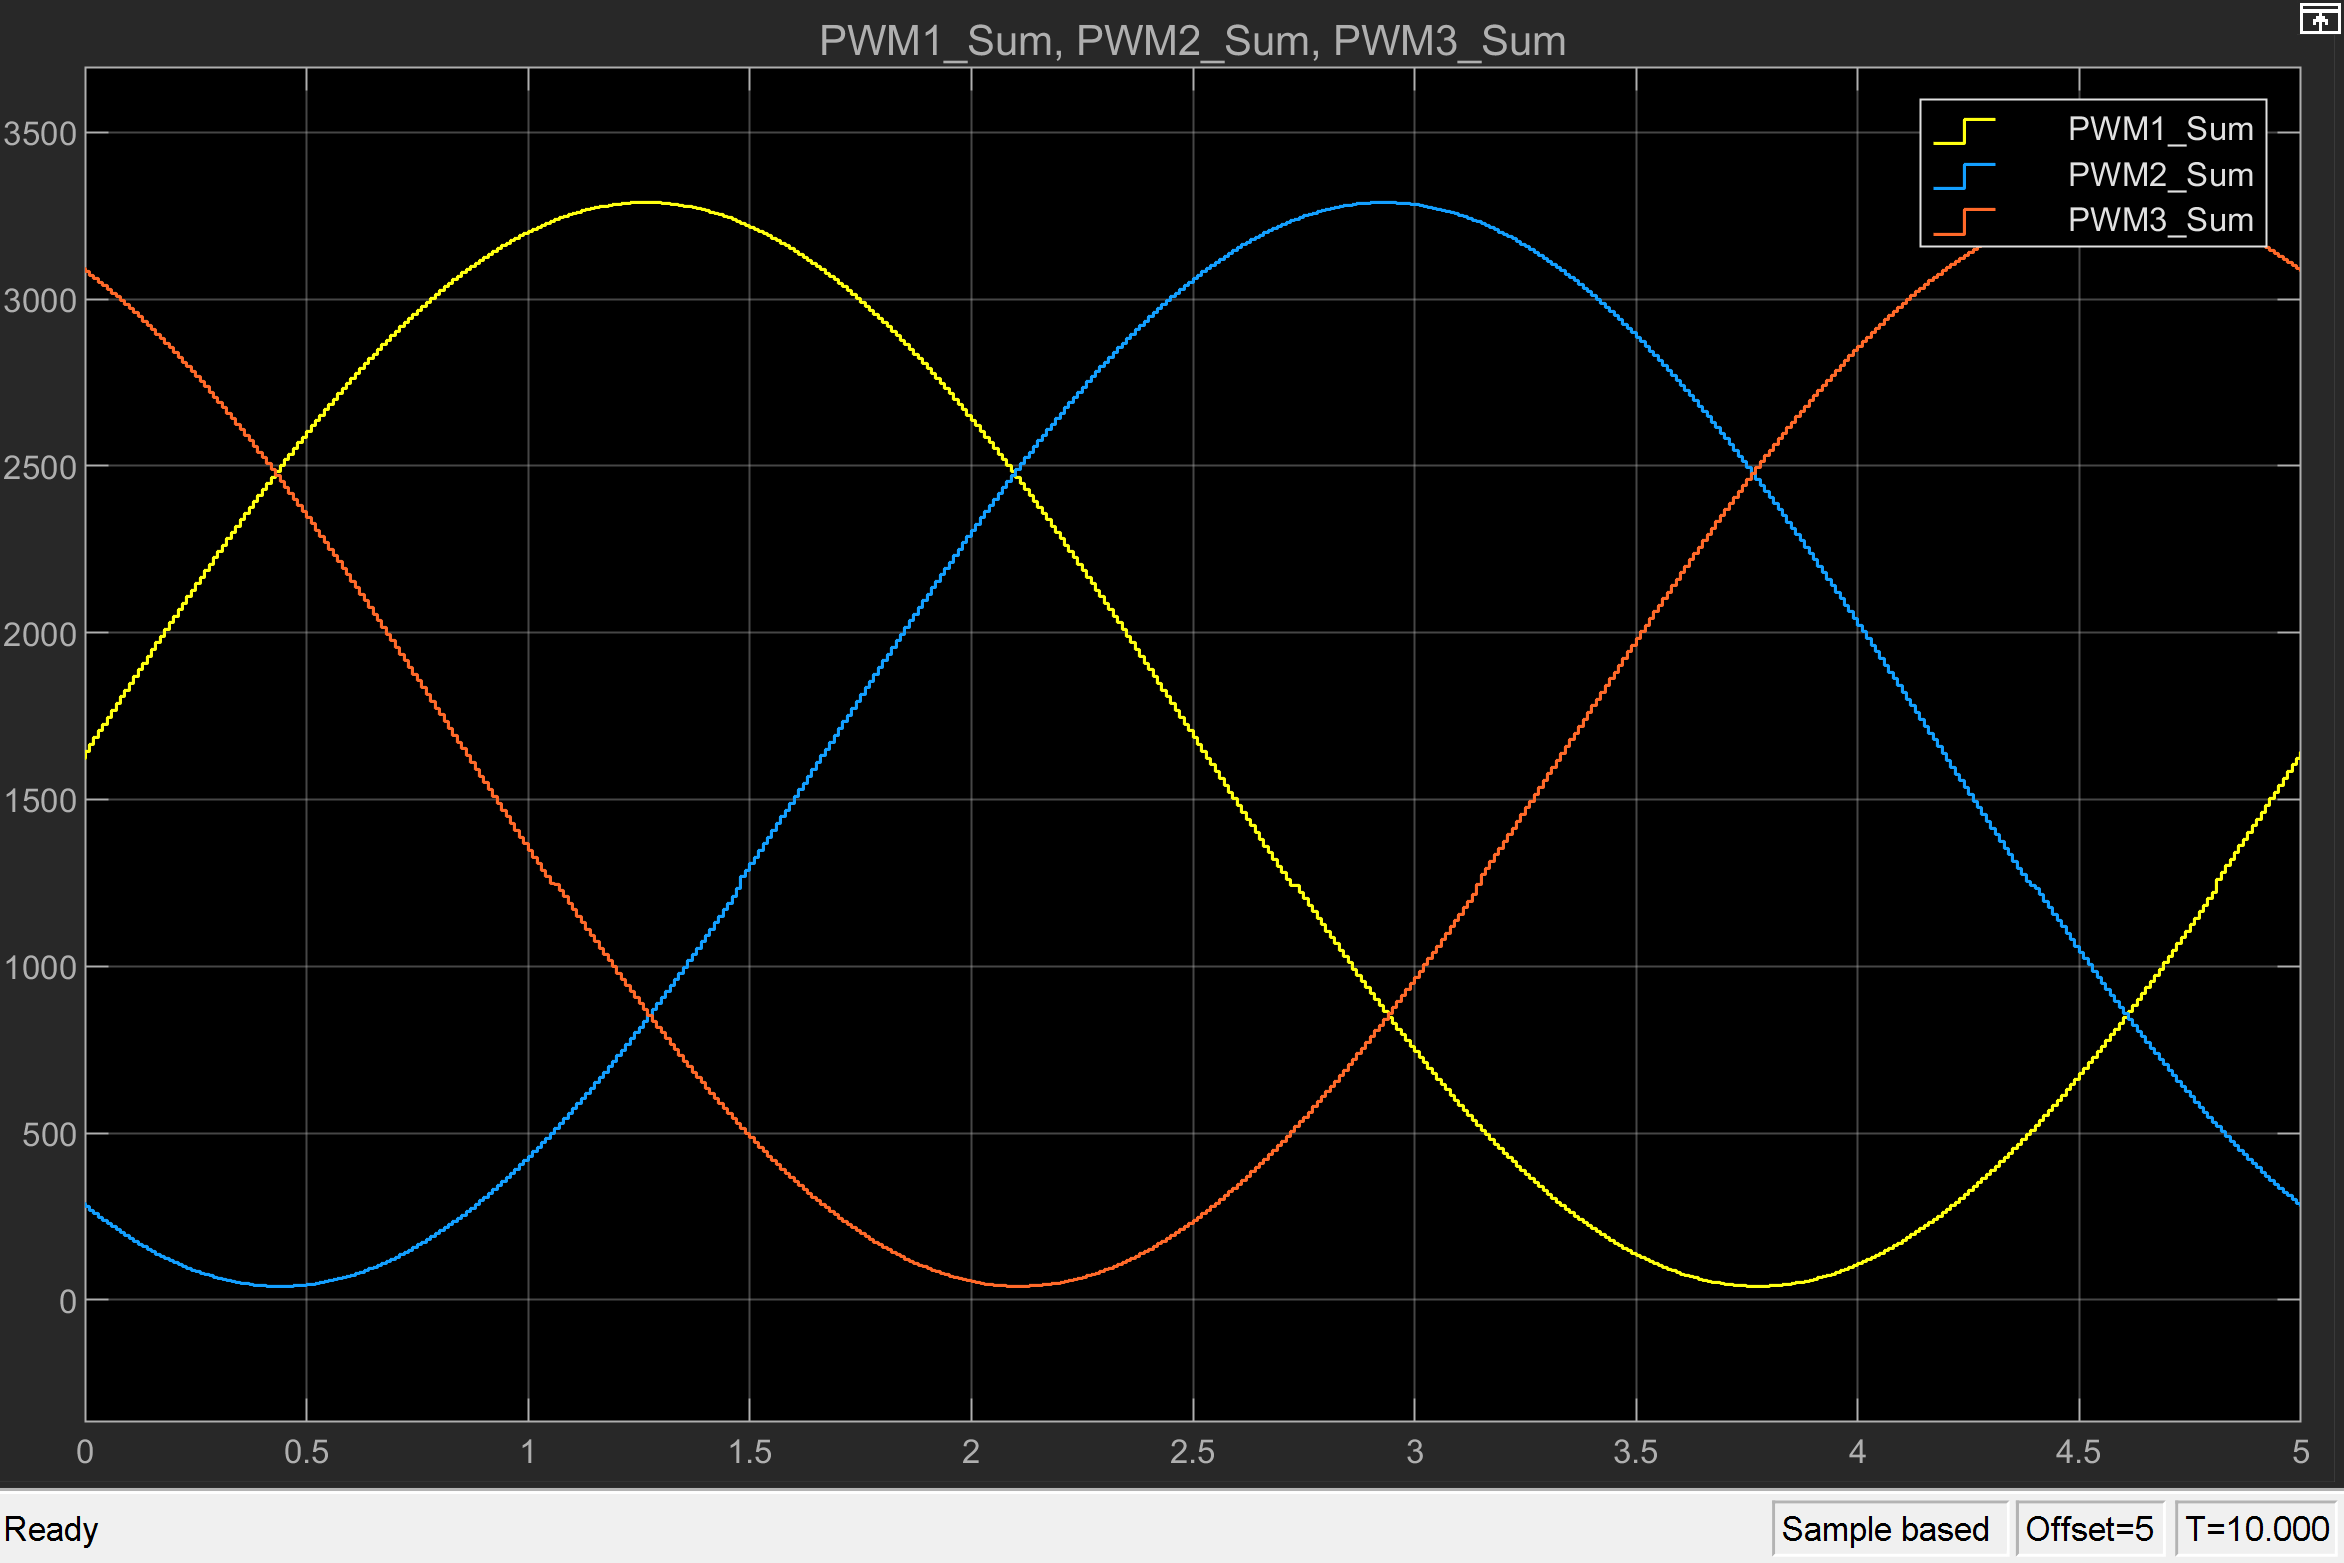

## Additional References

- [IO135 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io135)

- [IO Sync and PWM Generation documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io_sync_pwm_generation)